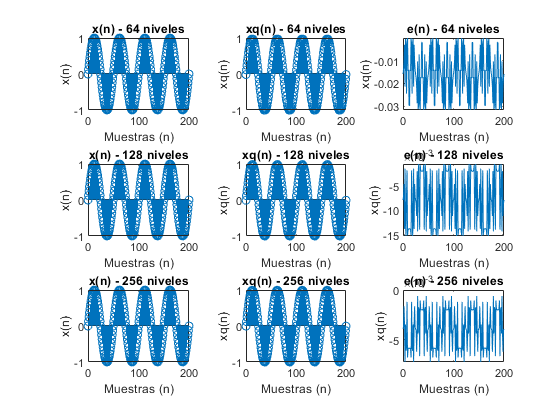

SQNR = 31.4200

SQNR = 37.3718

SQNR = 44.0576

clear; close all; clc;
N = 200;
n = 0:N;
f0 = 1/50;
x = sin(2*pi*f0*n);
quantificationLevels = [64, 128, 256];
figure('NumberTitle', 'off', 'Name', 'Cuantificación con truncamiento')
for i = 1:3
    subplot(3,3,1 + 3*(i-1))
    stem(n,x)
    title(sprintf("x(n) - %d niveles", quantificationLevels(i)))
    xlabel("Muestras (n)")
    ylabel("x(n)")
    
    xq = quantizer(x, quantificationLevels(i), 1, 'truncation');
    subplot(3,3,2+ 3*(i-1))
    stem(n,xq)
    title(sprintf("xq(n) - %d niveles", quantificationLevels(i)))
    xlabel("Muestras (n)")
    ylabel("xq(n)")
    
    e = xq - x;
    subplot(3,3,3+ 3*(i-1))
    plot(n,e)
    title(sprintf("e(n) - %d niveles", quantificationLevels(i)))
    xlabel("Muestras (n)")
    ylabel("xq(n)")
    
    Pq = mean(e.^2);
    Px = mean(x.^2);
    
    SQNR = 10*log10(Px / Pq)
    
end

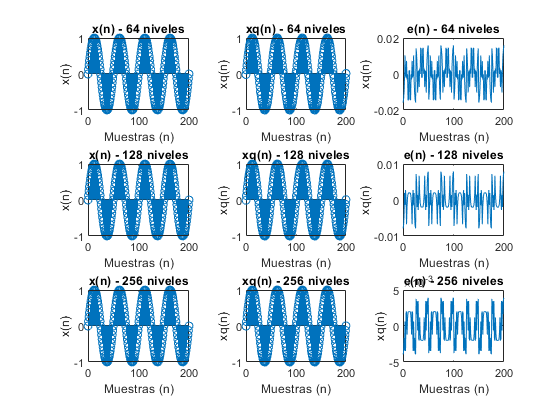

SQNR = 37.7441

SQNR = 45.3660

SQNR = 49.4589


figure('NumberTitle', 'off', 'Name', 'Cuantificación con redondeo')
for i = 1:3
    subplot(3,3,1 + 3*(i-1))
    stem(n,x)
    title(sprintf("x(n) - %d niveles", quantificationLevels(i)))
    xlabel("Muestras (n)")
    ylabel("x(n)")
    
    xq = quantizer(x, quantificationLevels(i), 1, 'rounding');
    subplot(3,3,2+ 3*(i-1))
    stem(n,xq)
    title(sprintf("xq(n) - %d niveles", quantificationLevels(i)))
    xlabel("Muestras (n)")
    ylabel("xq(n)")
    
    e = xq - x;
    subplot(3,3,3+ 3*(i-1))
    plot(n,e)
    title(sprintf("e(n) - %d niveles", quantificationLevels(i)))
    xlabel("Muestras (n)")
    ylabel("xq(n)")
    
    Pq = mean(e.^2);
    Px = mean(x.^2);
    
    SQNR = 10*log10(Px / Pq)
    
end

function quantizedSignal = quantizer(signal, levelsCount, expectedMax, type)
    levels = linspace(-expectedMax, expectedMax, levelsCount);
    quantizedSignal = zeros(1,length(signal));
    
    if strcmp(type, 'truncation')
        
        for i=1:length(signal)
            lesserValues = levels(levels <= signal(i));
            quantizedSignal(i) = lesserValues(end);
        end
        
    elseif strcmp(type, 'rounding')
        for i=1:length(signal)
            lesserValues = levels(levels <= signal(i));
            greaterValues = levels(levels >= signal(i));
            distanceBelow = signal(i) - lesserValues(end);
            distanceAbove = greaterValues(1) - signal(i);
            
            if distanceBelow <= distanceAbove
                quantizedSignal(i) = lesserValues(end);
            else
                quantizedSignal(i) = greaterValues(1);
            end
            
        end
        
    else
        error("Not a proper type of quantization")
    end
end